# Matlab基本操作

## 设置启动路径：

userpath("E:\MyGit\matlab\learning");
savepath; %一定要保存


# 一、在文件中创建函数

脚本和函数都允许您通过将命令序列存储在程序文件中来重用它们。脚本是最简单的程序类型，因为它们存储命令的方式与您在命令行中键入命令完全相同。函数提供的灵活性更大，主要因为您可以传递输入值并返回输出值。例如，名为 `fact` 的以下函数用于计算某个数 (`n`) 的阶乘并返回结果 (`f`)。

函数参考文末

此类型的函数必须在文件中而不是在命令行中定义。通常，您可以将函数存储在其自己的文件中。在这种情况下，最佳做法是对函数和文件使用相同的名称（此示例中为 `fact.m`），因为 MATLAB® 将程序与文件名相关联。将文件保存在当前文件夹中，或者保存在 MATLAB 搜索路径上的某个文件夹中。

您可以使用应用于随 MATLAB 一起安装的函数的相同语法规则从命令行调用函数。例如，计算 5 的阶乘。

x = 5;
y = fact(x) % 已在同一目录下定义了fact()求阶乘函数。

y = 120

## 1.1 从 R2016b 开始，用于存储函数的另一个选项是将函数包含在脚本文件的末尾。

例如，创建一个名为 `mystats.m` 并包含一些命令和两个函数 `fact` 和 `perm` 的文件。该脚本用于计算 (3,2) 的置换。

输入一下命令直接运行mystats.m脚本文件：

mystats %脚本保存在当前目录下；

z = 6

## 1.2 以下为脚本内容：

x = 3;
y = 2;
z = perm(x,y);


## **1.3 函数和文件的内容**

函数主体可以包括有效的 MATLAB 表达式、控制流语句、注释、空白行和嵌套函数。您在函数内创建的任何变量都存储在特定于该函数的工作区内，该工作区独立于基础工作区。

程序文件可以包含多个函数。如果文件仅包含函数定义，则第一个函数是主函数，也是 MATLAB 与文件名关联的函数。主函数或脚本代码后面的函数称为局部函数。局部函数只能在文件内使用。

## **1.4 End 语句**

函数以 [`end`](https://ww2.mathworks.cn/help/matlab/ref/end.html) 语句、文件末尾或局部函数的定义行结束，以先出现的为准。`end` 语句在以下情况下是必需的：

- 文件中的任何函数都包含嵌套函数（完全包含在其父级内的函数）。

- 该函数是函数文件中的局部函数，并且文件中有局部函数使用 `end` 关键字。

- 该函数是脚本文件内的局部函数。

虽然它有时是可选的，但使用 `end` 可提高代码可读性。

# 二、函数类型

## 2.1 局部函数

是在同一文件中可用的子例程。局部函数是拆分编程任务的最常见方法。在仅包含函数定义的函数文件中，局部函数可以任意顺序出现在文件中主函数的后面。在包含命令和函数定义的脚本文件中，局部函数必须位于文件末尾。（R2016b 或更高版本支持脚本中的函数。）

例如，创建一个名为 myfunction.m 的函数文件，其中包含主函数 myfunction 以及两个局部函数 squareMe 和 doubleMe：

函数参考文末

可以从命令行或另一程序文件中直接调用主函数，但局部函数仅适用于 myfunction。

## 2.2 嵌套函数

 嵌套函数完全包含在另一函数内。嵌套函数与局部函数的主要区别是，嵌套函数可以使用在父函数内定义的变量，无需将这些变量作为参数显式传递。

函数参考文末

创建一个函数，该函数允许您使用滑块或可编辑的文本框设置介于 0 与 1 之间的一个值。如果您将嵌套函数用于回调，滑块和文本框可以共享值和彼此的句柄，无需显式传递它们：

## 2.3 私有函数

- 子文件夹中的私有函数与局部或嵌套函数一样，私有函数仅供特定位置的函数访问。但是，私有函数与可以调用它们的函数不在同一个文件中。它们位于名称为 private 的子文件夹中。仅 private 文件夹紧邻的上一级文件夹内的函数可使用私有函数。使用私有函数将代码分割为不同的文件， 或在多个相关函数间共享代码。

## 2.4 匿名函数

- 无需文件的匿名函数只要函数包含一个语句，匿名函数即允许您定义该函数而不必创建程序文件。匿名函数通常用于定义数学表达式，然后使用 MATLAB® 复合函数（即接受函数句柄用作输入的函数）基于某个值范围计算该表达式。例如，以下语句为匿名函数创建名称为 s 的函数句柄：

s = @(x) sin(1./x);

- 该函数具有一个输入 x。@ 运算符创建函数句柄。您可以使用该函数句柄针对特定值计算函数，例如

y = s(pi);

- 您也可以将该函数句柄传递给在某一值范围内计算的函数，例如 fplot：

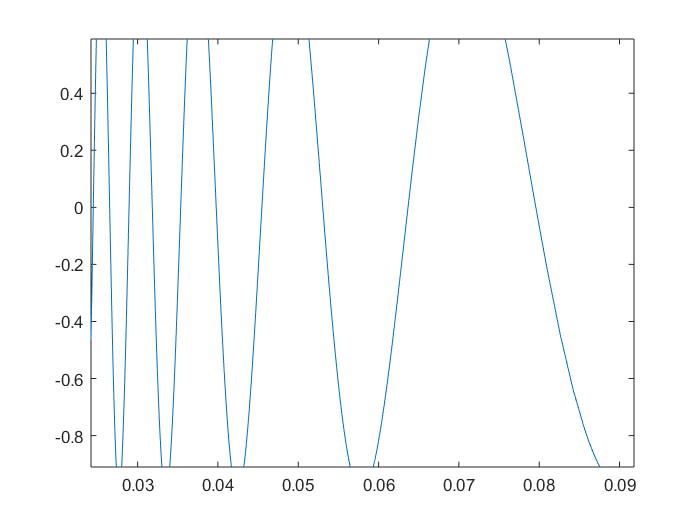

range = [0.01,0.1];
fplot(s,range)

xlim([0.0242 0.0918])
ylim([-0.91 0.59])

# 三、函数定义

## 3.1 函数语法

% function [y1,y2,...yn] = myfun(x1,x2,...xm)

## 3.2 函数说明

`function [y1,...,yN] = myfun(x1,...,xM)` 声明名为 `myfun` 的函数，该函数接受输入 `x1,...,xM` 并返回输出 `y1,...,yN`。此声明语句必须是函数的第一个可执行代码行。有效的函数名称以字母字符开头，并且可以包含字母、数字或下划线。

您可以将函数保存在以下位置：

- 只包含函数定义的函数文件中。文件的名称须与文件中第一个函数的名称一致。

- 包含命令和函数定义的脚本文件中。函数必须位于该文件的末尾。脚本文件不能与文件中的函数具有相同的名称。R2016b 或更高版本的脚本中支持函数。

文件可以包含多个局部函数或嵌套函数。为提高可读性，可使用 [`end`](https://ww2.mathworks.cn/help/matlab/ref/end.html) 关键字来表示文件中每个函数的末尾。以下情况下需要 `end` 关键字：

- 文件中有任意函数包含嵌套函数。

- 该函数是函数文件中的局部函数，并且文件中有局部函数使用 `end` 关键字。

- 该函数是脚本文件内的局部函数。

## 3.3 函数实例

### 3.3.1 包含一个输出的函数

在名为 `average.m` 的文件中定义一个函数，该函数接受一个输入向量，计算各个值的平均值，然后返回单个结果。

函数见文末

在命令行输入一下代码调用该函数：

z = 1:99;
ave = average(z)

ave = 50

### 3.3.2 包含多个输出的函数

函数见文末

运行一下命令调用该函数：

values = [12.7, 45.4, 98.9, 26.6, 53.1];
[ave,stdev] = stat(values)

ave = 47.3400

stdev = 29.4124

### 3.3.3 脚本文件中的函数

在名为 `integrationScript.m` 的文件中定义一个脚本，以计算被积函数在  处的值，并计算曲线下方从 0 到  的面积。包括一个局部函数，用于定义被积函数 。

函数见文末

脚本其它命令如下;

% Compute the value of the integrand at 2*pi/3.
x = 2*pi/3;
y = myIntegrand(x)

y = 0.6495


% Compute the area under the curve from 0 to pi.
xmin = 0;
xmax = pi;
f = @myIntegrand;
a = integral(f,xmin,xmax)

a = 1.3333

### 3.3.4 函数文件中的多个函数

在名为 `stat2.m` 的文件中定义两个函数，其中第一个函数调用第二个函数。

函数见文末

函数 `avg` 是*局部函数*。局部函数仅可供同一文件中的其他函数使用。

从命令行调用函数 `stat2`。

values = [12.7, 45.4, 98.9, 26.6, 53.1];
[ave,stdev] = stat2(values)

ave = 47.3400

stdev = 29.4124

### 3.3.5 带参数验证的函数

定义一个函数，该函数将输入限制为不包含 `Inf` 或 `NaN` 元素的数值向量。此函数使用 `arguments` 关键字，该关键字在 MATLAB® 版本 R2019b 及更高版本中为有效关键字。

函数见文末

在 `arguments` 代码块中，`(1,:)` 表示 `x` 必须为向量。验证函数 `{mustBeNumeric, mustBeFinite}` 将 `x` 中的元素限制为非 `Inf` 或 `NaN` 的数值。有关详细信息，请参阅[函数参数验证](https://ww2.mathworks.cn/help/matlab/matlab_prog/function-argument-validation-1.html)。

如果调用函数时所带的向量包含 `NaN` 元素，则违反了输入参数声明。此违规会导致 [`mustBeFinite`](https://ww2.mathworks.cn/help/matlab/ref/mustbefinite.html) 验证函数引发错误。

%values = [12.7, 45.4, 98.9, NaN, 53.1];
%[ave,stdev] = stat3(values)

# 函数区域

- 所有函数必须保存在脚本文件的最后；

- 在本地功能之前至少包含一行脚本代码；

- 每个局部函数必须以其自己的函数定义语句开头，并以`end`关键字结尾。

- 将局部函数添加到实时脚本时，MATLAB会在第一个局部函数定义之前自动添加分节符，并在其后删除所有分节符。

- 在`.mlx`文件中，只有在节位于本地函数定义之前，才可以运行节。

- 局部函数仅在定义它们的文件内可见。它们对其他文件中的函数不可见，因此无法从“命令窗口”中调用。

- 当您在脚本中调用函数时，MATLAB会先在其他位置查找该函数，然后再检查该函数是否为本地函数。

- 脚本在基本工作区中创建和访问变量。

- 像所有其他功能一样，局部功能也有其自己的工作空间，这些工作空间与基本工作空间分开。

- 局部函数无法访问其他函数的工作空间或基本工作空间中的变量，除非您将它们作为参数传递。

- 尽管无法从命令行或其他文件中的函数调用本地函数，但是可以使用`help`命令访问其帮助。

- 指定脚本和本地函数的名称，并用`>`字符分隔它们 。

- 例如：

help mystats>mymean


未找到 mystats>mymean。

请使用帮助浏览器的搜索字段搜索文档，或者
键入 "help help" 获取有关帮助命令选项的信息，例如方法的帮助。



function f = fact(n)
    f = prod(1:n);
end


function b = myfunction(a)
   b = squareMe(a)+doubleMe(a);
end
function y = squareMe(x) %后面两个为局部函数，仅限于 myfunction主函数使用；不可直接调用
   y = x.^2;
end
function y = doubleMe(x) 
   y = x.*2;
end


function myslider
value = 0;
f = figure;
s = uicontrol(f,'Style','slider','Callback',@slider);
e = uicontrol(f,'Style','edit','Callback',@edittext,...
                'Position',[100,20,100,20]);

   function slider(obj,~)
      value = obj.Value;
      e.String = num2str(value);
   end
   function edittext(obj,~)
      value = str2double(obj.String);
      s.Value = value;
   end

end


function p = perm(n,r) % 脚本中的函数必须位于脚本的结尾，放在前面不行;
    p = fact(n)*fact(n-r);
end


function ave = average(x)
    ave = sum(x(:))/numel(x); 
end

function [m,s] = stat(x)
    n = length(x);
    m = sum(x)/n;
    s = sqrt(sum((x-m).^2/n));
end

function y = myIntegrand(x)
    y = sin(x).^3;
end

function [m,s] = stat2(x)
    n = length(x);
    m = avg(x,n);
    s = sqrt(sum((x-m).^2/n));
end

function m = avg(x,n)
    m = sum(x)/n;
end

function [m,s] = stat3(x)
    arguments
        x (1,:) {mustBeNumeric, mustBeFinite}
    end
    n = length(x);
    m = avg(x,n);
    s = sqrt(sum((x-m).^2/n));
end